# Chapter 5, Section 1 (Part 2)

Let's do some more examples.

# Example #1

Consider the matrix


$$A=\pmatrix{1 & 0 & 0\cr 1 & 0 & 1\cr 2 & -2 & 3}$$


Find the eigenvalues and the corresponding eigenvectors for matrix $A$, then find a basis for each eigenspace corresponding to each eigenvalue.

**Soiution:** We first calculate the characteristic equation. To set up $|A-\lambda I|$, this time we will use our shortcut "subtract $\lambda$ from each diagonal element."


$$\left|\matrix{1-\lambda & 0 & 0\cr 1 & -\lambda & 1\cr 2 & -2 & 3-\lambda}\right|=0$$


We will use the cofactor expansion across the first row, ignoring the zero terms.


$$\begin{array}{rcl}
(1-\lambda)\left|\matrix{-\lambda & -1\cr -2 & 3-\lambda}\right|&=&0\\
(1-\lambda)((-3\lambda+\lambda^2)-(-2))
&=&0\\
(1-\lambda)(\lambda^2-3\lambda+2)&=&0\\
(1-\lambda)(\lambda-1)(\lambda-2)&=&0\\
-(\lambda-1)(\lambda-1)(\lambda-2)&=&0\\
(\lambda-1)^2(\lambda-2)&=&0
\end{array}$$


Let's check this with Matlab.

syms lambda
A=[1 0 0;1 0 1;2 -2 3];
p=charpoly(A,lambda)

$$p = \lambda^{3}-4\,\lambda^{2}+5\,\lambda -2$$

Matlab returns the characteristic polynomial $\lambda^3-4\lambda^2+5\lambda-2$. Let's expand our answer and see if it is the same.

expand((lambda-1)^2*(lambda-2)) 

$$ans = \lambda^{3}-4\,\lambda^{2}+5\,\lambda -2$$

We could also factor Matlab's answer.

factor(p)

$$ans = \left(\begin{array}{ccc} \lambda -2 & \lambda -1 & \lambda -1 \end{array}\right)$$

Same factors that we have. Now, our characteristic equation is


$$(\lambda-1)^2(\lambda-2)=0$$


so our eigenvalues are $\lambda_1=1$, which has algebraic multiplicity 2, and $\lambda_2=2$, which has algebraic multiplicity 1. We can check this with Matlab.

eig(A)

ans =      2
     1
     1


Nice. Matlab shows that 1 is an eigenvalue of multiplicty 2. Now we need to find the corresponding eigenvectors for each eigenvalue. For $\lambda_1=1$,


$$\begin{array}{rcl}
(A-\lambda_1I)\vec x&=&\vec 0\\
\left(\pmatrix{1 & 0 & 0\cr 1 & 0 & 1\cr 2 & -2 & 3}-1\pmatrix{1 & 0 & 0\cr 0 & 1 & 0\cr 0 & 0 & 1}\right)\pmatrix{x_1\cr x_2\cr x_3}&=&\pmatrix{0\cr 0\cr 0}\\
\pmatrix{0 & 0 & 0\cr1 & -1 & 1\cr 2 & -2 & 2}\pmatrix{x_1\cr x_2\cr x_3}&=&\pmatrix{0\cr 0\cr 0}\\ 
\end{array}$$


Note we could have also used our shortcut method "subtract $\lambda_1=1$ from each diagonal element." Now we set up our augmented matrix and row reduce.


$$\pmatrix{0 & 0 & 0 & 0\cr 1 & -1 & 1 & 0\cr 2 & -2 & 2 & 0}\ \matrix{R_1\leftrightarrow R_2\cr ~\cr ~}\ \qquad\longrightarrow\qquad\pmatrix{1 & -1 & 1 & 0\cr 0 & 0 & 0 & 0\cr 2 & -2 & 2 & 0}\ \matrix{~\cr ~\cr R_3-2R_1}\qquad\longrightarrow\qquad\pmatrix{1 & -1 & 1 & 0\cr 0 & 0 & 0 & 0\cr 0 & 0 & 0 & 0}$$


Because


$$\begin{array}{rcl}
\matrix{x_1\, & x_2\, & x_3 &~~\,\,}\\
\pmatrix{[1] & -1 & 1 & 0\cr 0 & 0 & 0 & 0\cr 0 & 0 & 0 & 0}\\
\matrix{p\,& f\,& f & ~~~}
\end{array}$$


we can write:


$$\begin{array}{rcl}
x_1-x_2+x_3&=&0\\
x_2&=&\text{free}\\
x_3&=&\text{free}
\end{array}$$


Now we solve the first equation for $x_1$ in terms of the free variables $x_2$ and $x_3$.


$$\begin{array}{rcl}
x_1&=&x_2-x_3\\
x_2&=&x_2\\
x_3&=&x_3
\end{array}$$


The solution can be written as: 


$$\pmatrix{x_1\cr x_2\cr x_3}=\pmatrix{x_2-x_3\cr x_2\cr x_3}=x_2\pmatrix{1\cr 1\cr 0}+x_3\pmatrix{-1\cr 0\cr 1}$$


Therefore, all eigenvectors in this eigenspace are linear combinations of these two vectors.  Note that they are linearly independent so


$$B_{V_{\lambda_1}}=\left\{\pmatrix{1\cr 1\cr 0},\ \pmatrix{-1\cr 0\cr 1}\right\}$$


is a basis for the eigenspace $V_{\lambda_1}$, having $\text{dim}{V_{\lambda_1}}=2$. Therefore, what is called the **geometric multiplicity **of $\lambda_1$ is 2. Note that the algebraic multiplicity was a 2 and the geometric multiplicity is a 2. We'll see that the geometric multiplicity is always less than or equal to the algebraic multiplicity. 

**Much Faster Way and Visualization: **Let's write our reduced row echelon matrix again. 


$$\begin{array}{rcl}
\matrix{x_1\, & x_2\, & x_3 &~~}\\
\pmatrix{[1] & -1 & 1 & 0\cr 0 & 0 & 0 & 0\cr 0 & 0 & 0 & 0}\\
\matrix{p\,& f\, & f & ~~}
\end{array}$$


Note that 1 times the first column, plus 1 times the second column, plus 0 times the third column equals the zero vector, so $(1,1,0)^T$ is an eigenvector. Second, note that $-1$ times the first column, plus 0 times the second column, plus 1 times the third column equals the zero vector, so $(-1,0,1)^T$ is an eigenvector. Thus, we have quickly determined that


$$B_{V_{\lambda_1}}=\left\{\pmatrix{1\cr 1\cr 0},\ \pmatrix{-1\cr 0\cr 1}\right\}$$


is the basis for the eigenspace corresponding to $\lambda=1$. Since all vectors in this eigenspace are linear combinations of these two vectors, we can write:


$$\pmatrix{x\cr y\cr z}=s\pmatrix{1\cr 1\cr 0}+t\pmatrix{-1\cr 0\cr 1}=\pmatrix{s-t\cr s\cr t}$$


Therefore, the eigenspace is a plane spanned by these two vectors. 

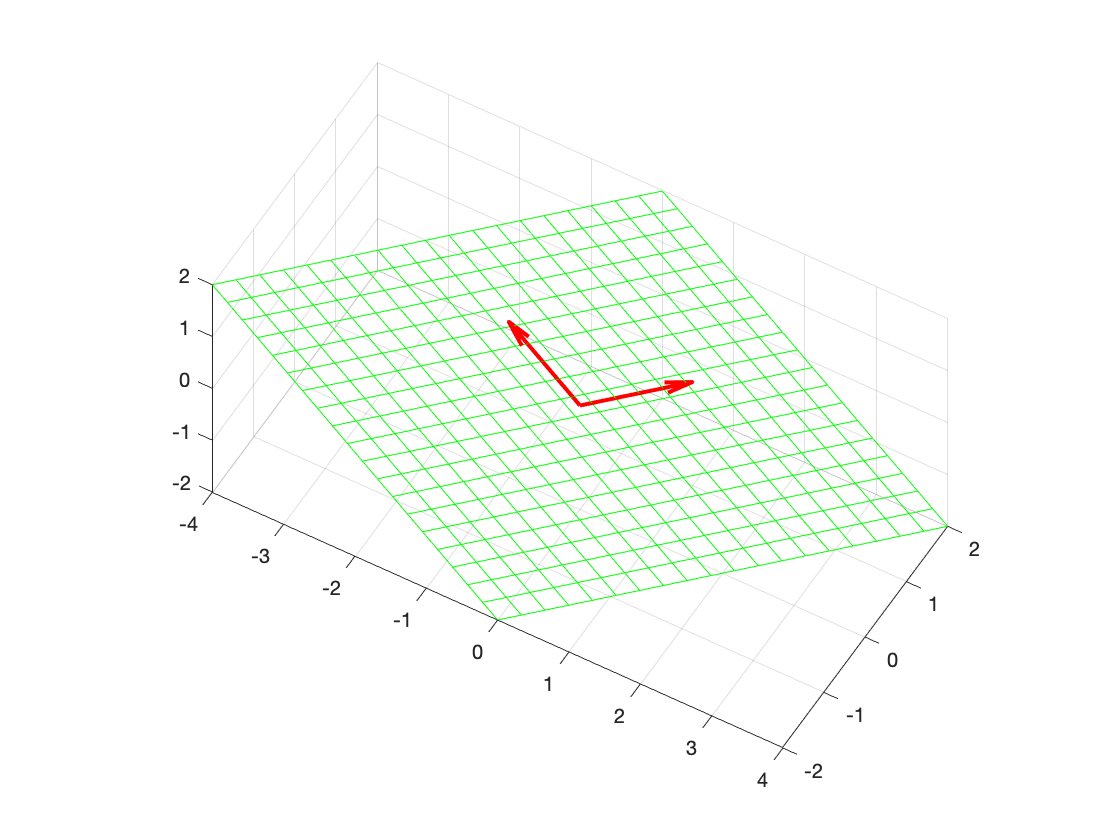

figure
s=linspace(-2,2,20);
t=linspace(-2,2,20);
[S,T]=meshgrid(s,t);
X=S-T; Y=S; Z=T;
mesh(X,Y,Z,'EdgeColor','green','FaceAlpha',0)
hold on
quiver3(0,0,0,1,1,0,0,'LineWidth',2,'Color','r','MaxHeadSize',1)
quiver3(0,0,0,-1,0,1,0,'LineWidth',2,'Color','r','MaxHeadSize',1)
axis equal
view(30,51)
hold off

Now, let's get the eigenspace of $\lambda_2=2$. 


$$\begin{array}{rcl}
(A-\lambda_2I)\vec x&=&\vec 0\\
\left(\pmatrix{1 & 0 & 0\cr 1 & 0 & 1\cr 2 & -2 & 3}-2\pmatrix{1 & 0 & 0\cr 0 & 1 & 0\cr 0 & 0 & 1}\right)\pmatrix{x_1\cr x_2\cr x_3}&=&\pmatrix{0\cr 0\cr 0}\\
\pmatrix{-1 & 0 & 0\cr 1 & -2 & 1\cr 2 & -2 & 1}\pmatrix{x_1\cr x_2\cr x_3}&=&\pmatrix{0\cr 0\cr 0}\\
\end{array}$$


Note that it would have been much quicker to simply subtract 2 from each diagonal element. Now we set up the augmented matrix and row reduce. 


$$\pmatrix{-1 & 0 & 0 & 0\cr 1 & 2 & -1 & 0\cr 2& -2 & 1 & 0}\ \matrix{-1R_1\cr ~\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 0 & 0\cr 1 & 2 & -1 & 0\cr 2 & -2 & 1 & 0}\ \matrix{~\cr R_2-R_1\cr R_3-2R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 0 & 0\cr 0 & 2 & -1 & 0\cr 0 & -2 & 1 & 0}$$


Next,


$$\pmatrix{1 & 0 & 0 & 0\cr 0 & 2 & -1 & 0\cr 0 & -2 & 1 & 0}\ \matrix{~\cr ~\cr R_3+R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 0 & 0\cr 0 & 2 & -1 & 0\cr 0 & 0 & 0 & 0}\ \matrix{~\cr (1/2)R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 0 & 0\cr 0 & 1 & -1/2 & 0\cr 0 & 0 & 0 & 0}$$


Because


$$\begin{array}{rcl}
\matrix{x_1\ & x_2\ \  & x_3 &~~~~}\\
\pmatrix{[1] & 0 & 0 & 0\cr 0 & [1] & -1/2 & 0\cr 0 & 0 & 0 & 0}\\
\matrix{p\ \,& p\,\ \, & f & ~~~~}
\end{array}$$


we can write:


$$\begin{array}{rcl}
x_1&=&0\\
x_2&=&\frac12x_3\\
x_3&=&\text{free}
\end{array}$$


Therefore,


$$\pmatrix{x_1\cr x_2\cr x_3}=\pmatrix{0\cr x_3/2\cr x_3}=x_3\pmatrix{0\cr 1/2\cr 1}$$


Therefore, a basis for the eigenspace corresponding to $\lambda_2=2$ is:


$$B_{V_{\lambda_2}}=\left\{\pmatrix{0\cr 1/2\cr 1}\right\}$$


The eigenspace $V_{\lambda_2}$ has one vector that spans the whole space, so its dimension is $\text{dim}(V_{\lambda_2})=1$. Therefore, the geometric multiplicity of $\lambda_2$ is 1. Note that it is less than or equal to the algebraic multiplicity, which was 1.

**Much Faster Way and Visualization: **Let's write our reduced row echelon matrix again. 


$$\begin{array}{rcl}
\matrix{x_1\ & x_2\ \  & x_3 &~~~~}\\
\pmatrix{[1] & 0 & 0 & 0\cr 0 & [1] & -1/2 & 0\cr 0 & 0 & 0 & 0}\\
\matrix{p\ \,& p\,\ \, & f & ~~~~}
\end{array}$$


Again, note that a much faster way is to recognize that 0 times the first column, plus 1/2 times the second column, plus 1 times the third column gives us the zero vector, so $(0,1/2,1)$ is an eigenvector. Thus, we have quickly determined that


$$B_{V_{\lambda_2}}=\left\{\pmatrix{0\cr 1/2\cr 1}\right\}$$


is a basis for the eigenspace corresponding to the eigenvector $\lambda_2=2$. Since all vectors in this eigenspace are linear combinations of this vector, we can write:


$$\pmatrix{x\cr y\cr z}=s\,\pmatrix{0\cr 1/2\cr 1}=\pmatrix{0\cr (1/2)s\cr s}$$


Therefore, this eigenspace is a line spanned by the single vector $(0,1/2,1)^T$.

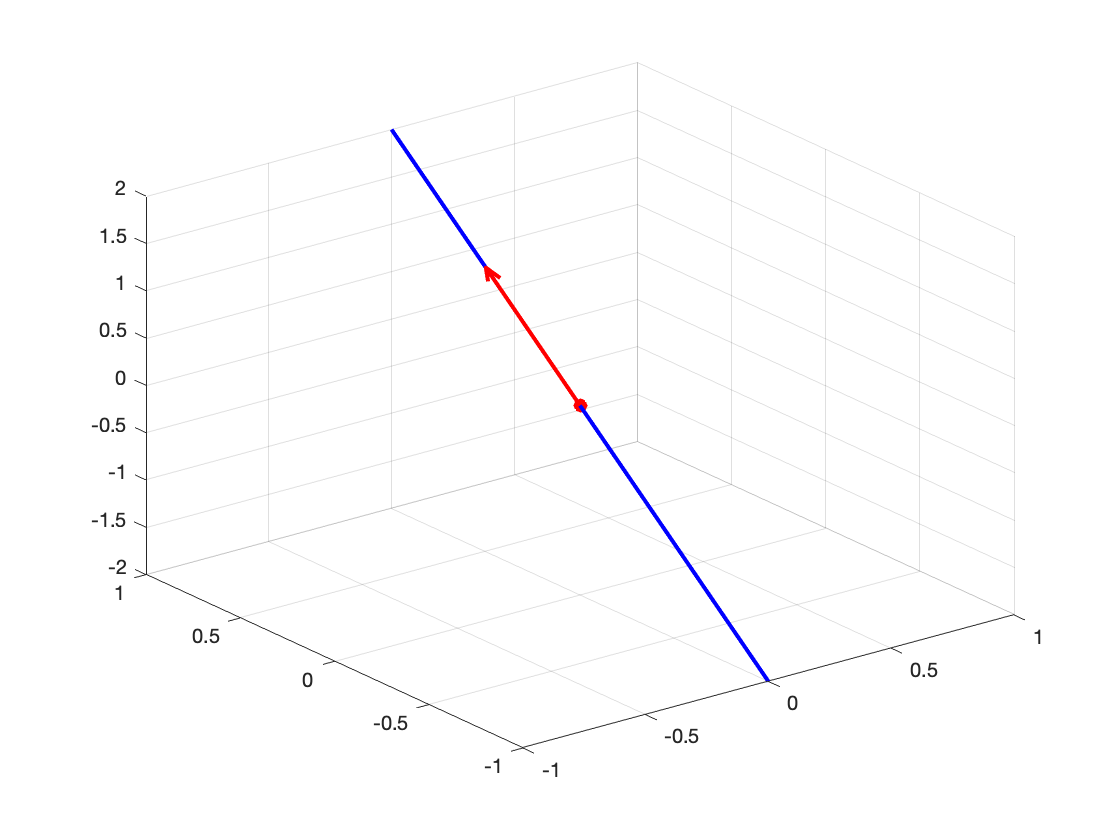

figure
s=linspace(-2,2);
x=zeros(size(s));
y=1/2*s;
z=s;
plot3(x,y,z,'LineWidth',2,'Color','b')
hold on
quiver3(0,0,0,0,1/2,1,0,'LineWidth',2,'Color','r','MaxHeadSize',0.3)
plot3(0,0,0,'ro','MarkerFaceColor','r')
grid on
axis([-1,1,-1,1,-2,2])
hold off

# Using Matlab's eig Command

We can check all of this work with Matlab's eig command. This time we will ask Matlab to return the eigenvalues and the eigenvectors, which we will store in the variables V and D.

[V,D]=eig(sym(A))

$$V = \left(\begin{array}{ccc} 0 & 1 & -1\\ \frac{1}{2} & 1 & 0\\ 1 & 0 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{ccc} 2 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

Two things to note:

- The eigenvalues are placed on the diagonal of matrix $D$ (a diagonal matrix). In the first column of $D$, the eigenvalue 2 has algebraic multiplicity 1. The corresponding eigenvector is in the first column of matrix $V$, $(0,1/2,1)^T$, so the geometric multiplicity is also 1.

- In the second and third columns of matrix $D$, the eigenvalue 1 is repeated twice, because it has algebraic multiplicity 2. The two different (and lnearly independent) corresponding eigenvectors are in the second and third columns of matrix $V$, $(1,1,0)^T$ and $(-1,0,1)^T$, so the geometric multiplicity is also 2.

# Rational Roots Theorem

Before we do the next example, we will review the Rational Roots Theorem from college algebra. Suppose that


$$f(x)=a_nx^n+a_{n-1}x^{n-1}+\cdots+a_0$$


is a polynomial with integer coefficients. If $a_n$ and $a_0$ are both nonzero, then any rational root, when written as a fraction $x=p/q$ reduced to lowest terms, satisifies:

- $p$ is an integer factor of $a_0$ (some might like to say $p$ divides $a_0$).

- $q$ is an integer factor of $a_n$ (some might like to say $q$ divides $a_n$).

For example, if $f(x)=x^3+2x^2-13x+10$, then $p$ might equal $\pm 1,\ \pm 2,\ \pm 5,\ \pm 10$, because $p$ must divide 10. Also, $q=\pm 1$, because $q$ must divide 1. So, possible rational roots are:


$$\frac{p}{q}=\pm 1,\ \pm 2, \ \pm 5,\ \pm 10$$


Now we can use long division to test if $x\pm 1$, $x\pm 2$, $x\pm 5$, or $x\pm 10$ are factors of our polynomial, but a much faster way is to use what is known a "short division." Put your guess for the root in the box at the top left, then put the coefficints of your polynomial on the top line to the right of the box, skip a line, draw a horizontal line, then repeat the first coefficient.

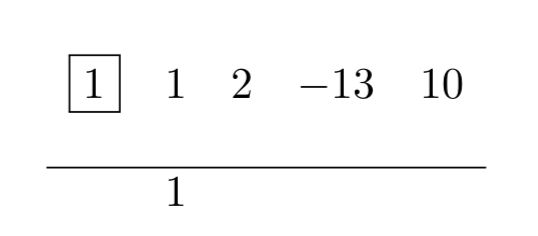

Now we multiply by the number in the box, then add. 

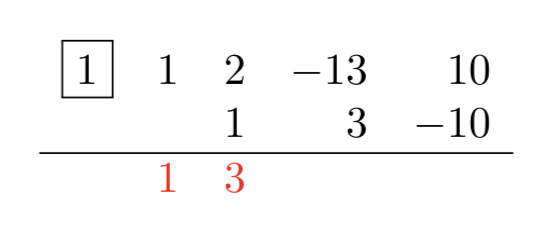

Now, we repeat this over and over; that is, multiply then add, multiply and add.

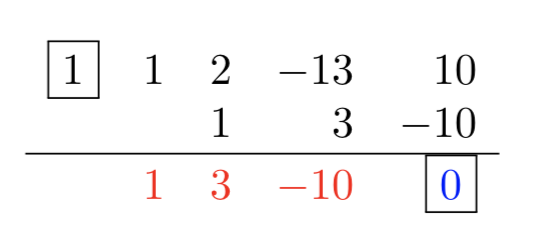

Now, because a 1 in the first box gives a zero in the second box, we know that $1$ is a rational root, so $x-1$ is a factor of our polynomial. Further, the numbers in red tells us what the quotient will be when we divide by $x-1$. Therefore, we now know that


$$f(x)=(x-1)(x^2+3x-10)$$


Now we know how to factor the quadratic polynomial, so our final answer is:


$$f(x)=(x-1)(x+5)(x-2)$$


Note that this means that 1, $-5$, and 2 are roots, and each of these rational roots are also on our list above. We can check this with Matlab.

syms x
f=x^3+2*x^2-13*x+10;
factor(f)

$$ans = \left(\begin{array}{ccc} x+5 & x-1 & x-2 \end{array}\right)$$

And we can use the solve command to find the roots.

solve(f==0,x)

$$ans = \left(\begin{array}{c} -5\\ 1\\ 2 \end{array}\right)$$

Same answer. Now, we have enough tools to try another example.

# Example #2

Consider the matrix


$$A=\pmatrix{0 & 1 & 0\cr 0 & 0 & 1\cr 2 & -5 & 4}$$


Find the eigenvalues and the corresponding eigenvectors for matrix $A$, then find a basis for each eigenspace corresponding to each eigenvalue. State the algebraic and geometric multiplicity of each eigenvalue.

**Solution:** We first find the characteristic equation. To set up $|A-\lambda I|$, we will use our shortcut "subtract $\lambda$ from each diagonal element."


$$\begin{array}{rcl}
|A-\lambda I|&=&0\\
\left|\matrix{-\lambda & 1 & 0\cr 0 & -\lambda & 1\cr 2 & -5 & 4-\lambda}\right|&=&0
\end{array}$$


Now we will do a cofactor expansion across the first row.


$$\begin{array}{rcl}
-\lambda\left|\matrix{-\lambda & 1\cr -5 & 4-\lambda}\right|-1\left|\matrix{0 & 1\cr 2 & 4-
\lambda}\right|&=&0\\
-\lambda(-4\lambda+\lambda^2+5)-(-2)&=&0\\
4\lambda^2-\lambda^3-5\lambda+2&=&0\\
\lambda^3-4\lambda^2+5\lambda-2&=&0
\end{array}$$


We can check this with Matlab.

syms lambda
A=[0 1 0;0 0 1;2 -5 4];
p=charpoly(A,lambda)

$$p = \lambda^{3}-4\,\lambda^{2}+5\,\lambda -2$$

Same answer. Now we can use the rational root theorem to factor this polynomial; $p$ must divide $-2$ and $q$ must divide 1, so:

- 
$$p=\pm 1,\ \pm 2$$


- 
$$q=\pm 1$$


- 
$$\frac{p}{q}=\pm 1,\ \pm 2$$


Using short division, we get:

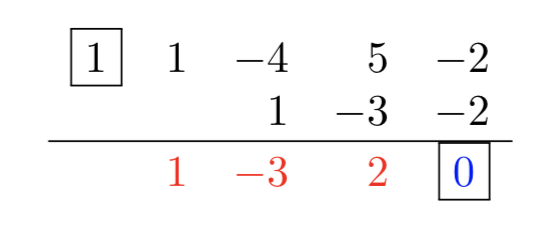

Therefore, our polynomial factors as follows.


$$\begin{array}{rcl}
\lambda^3-4\lambda^2+5\lambda-2&=&0\\
(\lambda-1)(\lambda^2-3\lambda+2)&=&0
\end{array}$$


Now we can factor the quadratic factor.


$$\begin{array}{rcl}
(\lambda-1)(\lambda-1)(\lambda-2)&=&0\\
(\lambda-1)^2(\lambda-2)&=&0
\end{array}$$


Therefore, $\lambda_1=1$ is an eigenvalue of algebraic multiplicity 2 and $\lambda_2=2$ is an eigenvalue of algebraic multiplicity 1. We can check this work with Matlab.

factor(p)

$$ans = \left(\begin{array}{ccc} \lambda -2 & \lambda -1 & \lambda -1 \end{array}\right)$$

solve(p==0,lambda)

$$ans = \left(\begin{array}{c} 1\\ 1\\ 2 \end{array}\right)$$

Same answers. Now we have to determine the corresponding eigenvectors. First, $\lambda_1=1$. Recall that


$$A=\pmatrix{0 & 1 & 0\cr 0 & 0 & 1\cr 2 & -5 & 4}$$


and a very fast way to compute $A-\lambda I$ is to subtract $\lambda$ from each diagonal element. So, for $\lambda_1=1$, we will subtract 1 from each diagonal element.


$$\begin{array}{rcl}
(A-\lambda_1 I)\vec x&=&\vec 0\\
\pmatrix{-1 & 1 & 0\cr 0 & -1 & 1\cr 2 & -5 & 3}\pmatrix{x_1\cr x_2\cr x_3}&=&\pmatrix{0\cr 0\cr 0}
\end{array}$$


Now we set up the augmented matrix and row reduce.


$$\pmatrix{-1 & 1 & 0 & 0\cr 0 & -1 & 1 & 0\cr 2 & -5 & 3 & 0}\ \matrix{-R_1\cr -R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & -1 & 0 & 0\cr 0 & 1 & -1 & 0\cr 2 & -5 & 3 & 0}\ \matrix{~\cr ~\cr R_3-2R_1}\qquad\longrightarrow\qquad\pmatrix{1 & -1 & 0 & 0\cr 0 & 1 & -1 & 0\cr 0 & -3 & 3 & 0}$$


Next,


$$\pmatrix{1 & -1 & 0 & 0\cr 0 & 1 & -1 & 0\cr 0 & -3 & 3 & 0}\ \matrix{R_1+R_2\cr ~\cr R_3+3R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & -1 & 0\cr 0 & 1 & -1 & 0\cr 0 & 0 & 0 & 0}$$


We can check this with Matlab.

rref([A-1*eye(3),zeros(3,1)])

ans =      1     0    -1     0
     0     1    -1     0
     0     0     0     0


Same answer. 


$$\begin{array}{rcl}
\matrix{x_1\ & x_2\ & x_3 & ~~~~~}\\
\pmatrix{[1] & 0 & -1 & 0\cr 0 & [1] & -1 & 0\cr 0 & 0 & 0 & 0 & ~}\\
\matrix{p\ & p\ & f &~~~~~~}
\end{array}$$


Therefore, 


$$\begin{array}{rcl}
x_1-x_3&=&0\\
x_2-x_3&=&0\\
x_3&=&\text{free}
\end{array}$$


Solving for the pivot variables in terms of the free variable gives us:

$\begin{array}{rcl}
x_1&=&x_3\\
x_2&=&x_3\\
x_3&=&x_3
\end{array}$          which can be written as         $\pmatrix{x_1\cr x_2\cr x_3}=\pmatrix{x_3\cr x_3\cr x_3}=x_3\pmatrix{1\cr 1\cr 1}$

Hence, a basis for the eigenspace $V_{\lambda_1}$ is


$$B_{V_{\lambda_1}}=\left\{\pmatrix{1\cr 1\cr 1}\right\}$$


so the geometric multiplicity of $\lambda_1=1$ is 1. Recall that the algebraic multiplicty of $\lambda_1=1$ was 2. It is a fact that the geometric multiplicty of an eigenvalue is always less than or equal to the algebraic multiplicity. Note again that a much faster way to determine the basis


$$\begin{array}{rcl}
\pmatrix{[1] & 0 & -1 & 0\cr 0 & [1] & -1 & 0\cr 0 & 0 & 0 & 0}
\end{array}$$


is to note that the dependent third column is equal to $-1$ times the first column plus $-1$ times the second column, so we can write: 


$$1\pmatrix{1\cr 0\cr 0}+1\pmatrix{0\cr 1\cr 0}+1\pmatrix{-1\cr -1\cr 0}=\pmatrix{0\cr 0\cr 0}$$


so $(1,1,1)^T$ is an eigenvector. Now we'll get the eigenvector for $\lambda_2=2$.Recall that


$$A=\pmatrix{0 & 1 & 0\cr 0 & 0 & 1\cr 2 & -5 & 4}$$


Now we simply subtract 2 from each diagonal element of matrix $A$.


$$\begin{array}{rcl}
(A-\lambda_2I)\vec x&=&\vec 0\\
\pmatrix{-2 & 1 & 0\cr 0 & -2 & 1\cr 2 & -5 & 2}\pmatrix{x_1\cr x_2\cr x_3}&=&\pmatrix{0\cr 0\cr 0}
\end{array}$$


Let's set up the augmented matrix using Matlab.

([A-2*eye(3),zeros(3,1)])

ans =     -2     1     0     0
     0    -2     1     0
     2    -5     2     0


Looks good. Now, let's row reduce.

rref(sym([A-2*eye(3),zeros(3,1)]))

$$ans = \left(\begin{array}{cccc} 1 & 0 & -\frac{1}{4} & 0\\ 0 & 1 & -\frac{1}{2} & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

Now, we note that the third dependent column is equal to $-1/4$ times the first column, plus $-1/2$ times the second coluimn, so we see that:


$$\frac14\pmatrix{1\cr 0\cr 0}+\frac12\pmatrix{0\cr 1\cr 0}+1\pmatrix{-1/4\cr -1/2\cr 0}=\pmatrix{0\cr 0\cr 0}$$


Therefore, an eigenvector corresponding to $\lambda_2=2$ is


$$\vec v_2=\pmatrix{1/4\cr 1/2\cr 1}$$


However, any multple of an eigenvector is also an eigenvector, so we will multiply this result by 4 and use the following as our eigenvector corresponding to $\lambda_2=2$.


$$\vec v_2=\pmatrix{1\cr 2\cr 4}$$


Therefore, a basis for the eigenspace $V_{\lambda_2}$ corresponding to the eigenvaluel $\lambda_2=2$ is:


$$B_{V_{\lambda_2}}=\left\{\pmatrix{1\cr 2\cr 4}\right\}$$


Note that this means that the geometric multiplicity of $\lambda_2$ is 1, which is less than or equal to the algebraic multiplicity of $\lambda_2$, which is also 1. Now, let's check these eigenvalues and eigenvectors with Matlab's eig command.

[V,D]=eig(sym(A))

$$V = \left(\begin{array}{cc} \frac{1}{4} & 1\\ \frac{1}{2} & 1\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{ccc} 2 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

The diagonal matrix D contains two ones (algebraic multiplicty 2) and one two (algebraic multiplicity 1). Note that our $(1/4,1/2,1)^T$ is in the first column of V, corresponding to the eigenvalue 2 in the first column of D. Hence, geometric multiplicity 1. However, the eigenvector $(1,1,1)^T$ in the second column of V corresponds to the eigenvalue 1 in the second and third columns of matrix D. Hence, geometric multiplicity 1. Again, note that the geometric multiplicity is less than or equal to the algebraic multiplicity for each eigenvalue.